Fonte: [https://www.mathworks.com/help/ident/ug/generating-data-using-simulation.html](https://www.mathworks.com/help/ident/ug/generating-data-using-simulation.html)

**Create Periodic Input Data**

Criar input de dados equivalente a 24 medições em um dia

measurements = idinput([24 1 1]);

Criar um objeto iddata usando o input de dados

u = iddata([],measurements,'Period',.24);

Definindo o tempo do objeto como hora

u.ti = 'hours';
%plot(u);
%spectrum(spa(u));

Simular modelo de output utilizando os dados

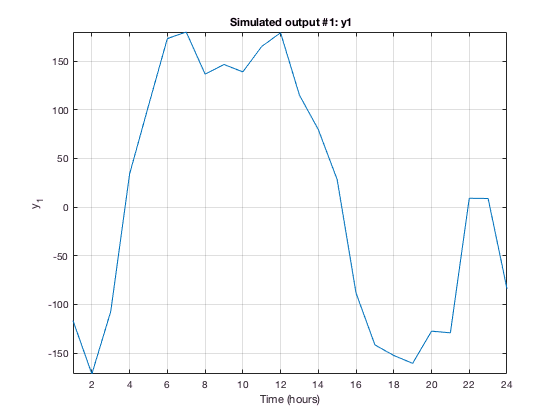

% Construct a polynomial model.
m0 = idpoly([1 -1.5 0.7],[0 1 0.5]);
% Simulate model output with Gaussian noise.
sim_opt = simOptions('AddNoise',true);
sim(m0,u,sim_opt);